## Ploting Parameters

linewidth  = 2;
fontname   = 'TImes New Roman';
fontsize   = 20;
markersize = 10;

M = 64;
K = 18;
L = 13;

R = 200;
r = sqrt(3)/2*R;

theta_mid  = 0;
theta_step = pi/18;
theta_0    = theta_mid - theta_step/2;


$$r_{12} = \frac{ | \mathbf{h}_{1}^{\mathrm{H}} \mathbf{h}_{2} | }{ \Vert \mathbf{h}_{1} \Vert_{2} \Vert \mathbf{h}_{2} \Vert_{2} }$$



$$r_{12} = \frac{1}{M} \left | \mathrm{e}^{ -\mathrm{j}(\phi_{1} - \phi_{2})} \left [ \frac{1 - \mathrm{e}^{\mathrm{j}M\pi (\sin\theta_{1} - \sin\theta_{2})}}{1 - \mathrm{e}^{\mathrm{j}\pi (\sin\theta_{1} - \sin\theta_{2})}} \right]  \right|$$



$$r_{12} = \frac{1}{M} \left | \frac{\mathrm{e}^{\mathrm{j} M \frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2})}}{\mathrm{e}^{\mathrm{j}\frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2})}} \left [ \frac{\mathrm{e}^{\mathrm{j} M \frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2})} - \mathrm{e}^{-\mathrm{j} M \frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2})}}{\mathrm{e}^{\mathrm{j}\frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2})} - \mathrm{e}^{-\mathrm{j}\frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2})}} \right]  \right|$$



$$r_{12} = \frac{1}{M} \left | \frac{\sin \left( M \frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2}) \right) }{\sin \left( \frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2}) \right)} \right|$$


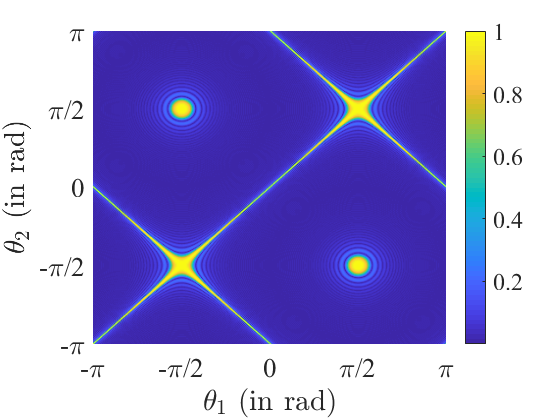

r_12 = @(theta_1,theta_2) abs(sin(M*pi/2*(sin(theta_1) - sin(theta_2) + eps))./sin(pi/2*(sin(theta_1) - sin(theta_2) + eps)))/M;

theta_corr = -pi:pi/180:pi;
[T_1,T_2] = meshgrid(theta_corr,theta_corr);

surf(T_1,T_2,r_12(T_1,T_2),'edgecolor','none');
view(2);

xlabel('$\theta_{1}$ (in rad)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('$\theta_{2}$ (in rad)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
zlabel('Correlation coefficient','fontname',fontname,'fontsize',fontsize);

xticks([-pi -pi/2 0 pi/2 pi]);
xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'});

yticks([-pi -pi/2 0 pi/2 pi]);
yticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'});

xlim([-pi, pi]);
ylim([-pi, pi]);
zlim([0 1]);

set(gca,'fontname',fontname,'fontsize',fontsize);
colorbar;

x_cell = [R R/2 -R/2 -R -R/2 R/2 R]';                                % Cell's x-coordinates
y_cell = [0 r    r    0 -r  -r   0]';                                % Cell's y-coordinates

% [x_corr,y_corr] = pol2cart(theta,r*r_12(theta_1,theta_2));

radius = r*sqrt(rand(K,1));
theta  = theta_0 +  theta_step*rand(K,1);

x = radius.*cos(theta);
y = radius.*sin(theta);

N_CIRCLE_POINTS = 100;

theta_spread = theta_0 + theta_step*linspace(0,1,N_CIRCLE_POINTS);

x_spread = r*cos(theta_spread);
y_spread = r*sin(theta_spread);

## Distribution of the Users in a Small Piece of the Cell

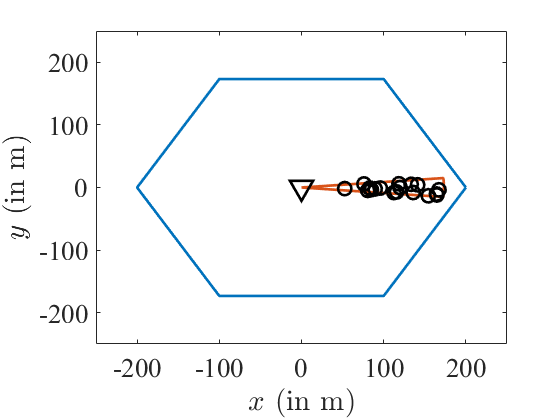

plot(x_cell,y_cell,'linewidth',linewidth);
hold on;
% plot(x_corr,y_corr,'linewidth',linewidth);
plot([0 x_spread 0],[0 y_spread 0],'linewidth',linewidth);
plot(0,0,'vk','linewidth',linewidth,'markersize',1.5*markersize);
plot(x,y,'ok','linewidth',linewidth,'markersize',markersize);
xlabel('$x$ (in m)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('$y$ (in m)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');

set(gca,'fontname',fontname,'fontsize',fontsize);
xlim([-1.25*R 1.25*R]);
ylim([-1.25*R 1.25*R]);